## Question D

clear
clc
R = 1;
KE = 1e-1;
KT = 1e-1;
J1 = 1e-5;
J2 = 4e-5;
Bf = 2e-3;
D1 = 20;
D2 = 2;

A = [0 0 0 1 0;
     0 0 0 0 1;
     0 (D2/Bf) -(D2/Bf) 0 0;
     -(D1/J1) (D1/J1) 0 -(KT*KE/J1/R) 0;
     (D1/J2) -((D1+D2)/J2) (D2/J2) 0 0];

eigenvalue = eig(A)

eigenvalue = 1.0e+03 *

  -0.3914 + 1.4791i
  -0.3914 - 1.4791i
  -0.0000 + 0.0000i
  -0.2708 + 0.0000i
  -0.9464 + 0.0000i



B = [0 0;
     0 0;
     0 1/Bf;
     KT/J1/R 0;
     0 0];

#### case (1)

C_1 = [0 1 0 0 0;
       0 0 0 0 1];
D_1 = [0 0;
       0 0];

sys_1 = ss(A,B,C_1,D_1);
tf_1 = tf(sys_1);
[p1,z1]=pzmap(sys_1)

p1 = 1.0e+03 *

  -0.3914 + 1.4791i
  -0.3914 - 1.4791i
  -0.0000 + 0.0000i
  -0.2708 + 0.0000i
  -0.9464 + 0.0000i



z1 =

  0×1 empty double column vector



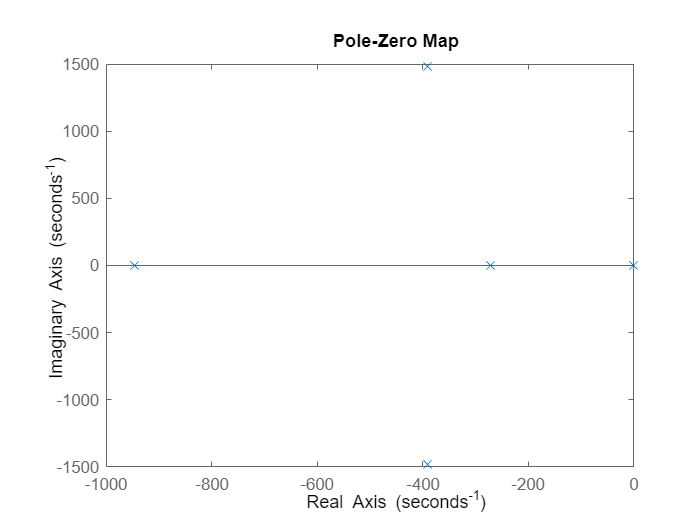

pzmap(sys_1);

#### case(2)

C_2 = [0 0 0 -KE/R 0;
       0 D2/Bf -D2/Bf 0 0];
D_2 = [1/R 0;
       0 1/Bf];

sys_2 = ss(A,B,C_2,D_2);
tf_2 = tf(sys_2);
[p21,z21]=pzmap(sys_2)

p21 = 1.0e+03 *

  -0.3914 + 1.4791i
  -0.3914 - 1.4791i
  -0.0000 + 0.0000i
  -0.2708 + 0.0000i
  -0.9464 + 0.0000i


z21 = 1.0e+03 *

   0.0000 + 0.0000i
  -0.0000 + 1.5843i
  -0.0000 - 1.5843i
  -0.0000 + 0.1996i
  -0.0000 - 0.1996i


sysr_2=minreal(sys_2);%zero-pole cancellation

1 state removed.


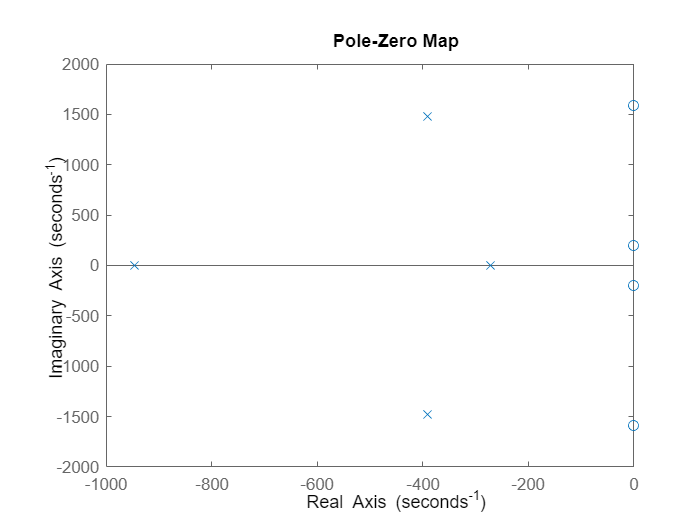

pzmap(sysr_2)

[p22,z22]=pzmap(sysr_2)

p22 = 1.0e+03 *

  -0.3914 + 1.4791i
  -0.3914 - 1.4791i
  -0.2708 + 0.0000i
  -0.9464 + 0.0000i


z22 = 1.0e+03 *

  -0.0000 + 1.5843i
  -0.0000 - 1.5843i
  -0.0000 + 0.1996i
  -0.0000 - 0.1996i


## Question E

B_3 = [0;
       0;
       0;
       KT/J1;
       0];
C_3 = [0 0 0 -KE/R 0;
       0 D2/Bf -D2/Bf 0 0];
D_3 = [1/R;
       0];
sys_3 = ss(A,B_3,C_3,D_3);
tf_3 = tf(sys_3)

tf_3 =
 
  From input to output...
       s^5 + 1000 s^4 + 2.55e06 s^3 + 2.5e09 s^2 + 1e11 s + 0.01988
   1:  -------------------------------------------------------------
       s^5 + 2000 s^4 + 3.55e06 s^3 + 3.05e09 s^2 + 6e11 s + 0.05601
 
                                  5e12 s
   2:  -------------------------------------------------------------
       s^5 + 2000 s^4 + 3.55e06 s^3 + 3.05e09 s^2 + 6e11 s + 0.05601
 
Continuous-time transfer function.



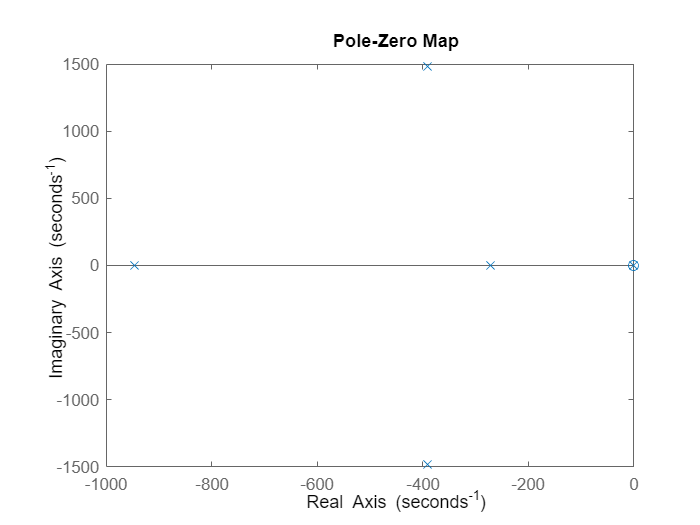


pzmap(sys_3);

[p31,z31]=pzmap(sys_3)

p31 = 1.0e+03 *

  -0.3914 + 1.4791i
  -0.3914 - 1.4791i
  -0.0000 + 0.0000i
  -0.2708 + 0.0000i
  -0.9464 + 0.0000i


z31 = -1.7598e-14

sysr_3=minreal(sys_3); %zero-pole cancellation

1 state removed.


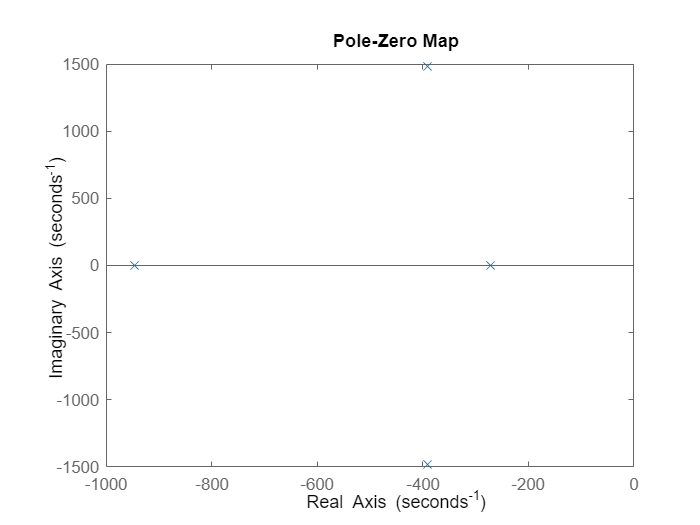

pzmap(sysr_3);

[p32,z32]=pzmap(sysr_2)

p32 = 1.0e+03 *

  -0.3914 + 1.4791i
  -0.3914 - 1.4791i
  -0.2708 + 0.0000i
  -0.9464 + 0.0000i


z32 = 1.0e+03 *

  -0.0000 + 1.5843i
  -0.0000 - 1.5843i
  -0.0000 + 0.1996i
  -0.0000 - 0.1996i



%num_3 = tf_3.Numerator;
%den_3 = tf_3.Denominator;
%for i = 1:2
   %[z3,p3,k3] = tf2zp(num_3{i,1},den_3{i,1});
   %[z4,p4,k4] = residue(num_3{1,1},den_3{1,1);
   % Plot the poles and zeros to verify that they are in the expected locations.
%    fvtool(num_3{i,1},den_3{i,1},'polezero');
%end

## Question F

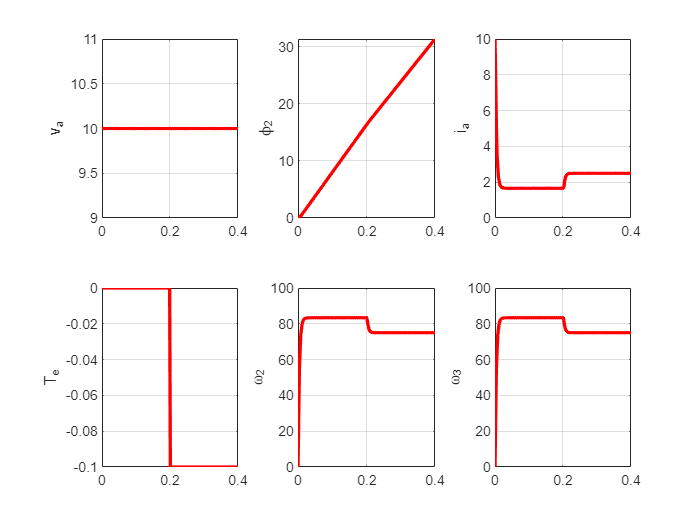

t = linspace(0,0.4,200);
u = [10*ones(size(t));
      0*ones(1,length(t)/2) -0.1*ones(1,length(t)/2)];
[y1,t1] = lsim(sys_1,u,t);
[y2,t2] = lsim(sys_2,u,t);

figure(1)
subplot(2,3,1)
plot(t1,u(1,:),'Color','r','LineWidth',2); grid on;
ylabel('v_a')
subplot(2,3,4)
plot(t1,u(2,:),'Color','r','LineWidth',2); grid on;
ylabel('T_e')
hold on

subplot(2,3,2)
plot(t1,y1(:,1),'Color','r','LineWidth',2); grid on;
ylabel('\phi_2')
subplot(2,3,5)
plot(t1,y1(:,2),'Color','r','LineWidth',2); grid on;
ylabel('\omega_2')
hold on

subplot(2,3,3)
plot(t2,y2(:,1),'Color','r','LineWidth',2); grid on;
ylabel('i_a')
subplot(2,3,6)
plot(t1,y1(:,2),'Color','r','LineWidth',2); grid on;
ylabel('\omega_3')
hold on